# Boundary Condition =[1 0;0 1]

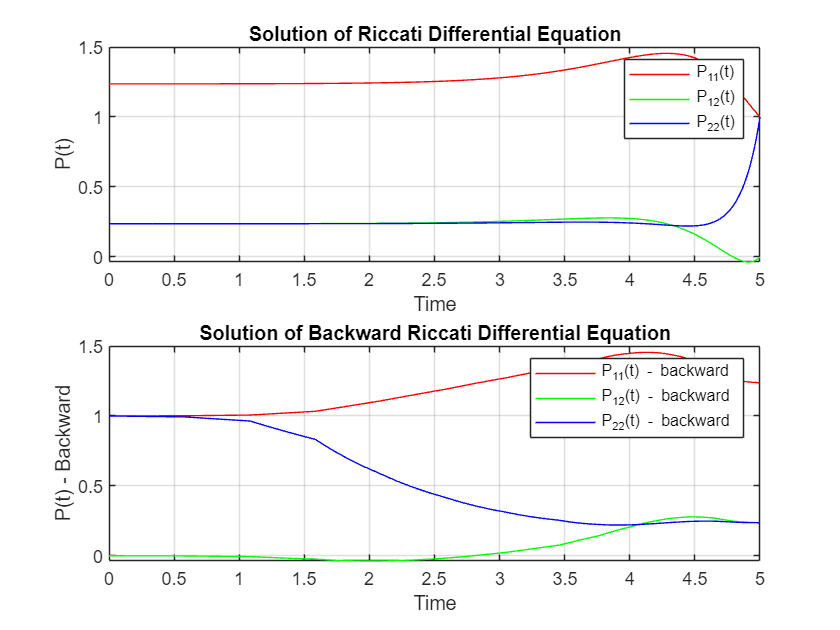

clear 
clc
close 
% Define system matrices
A = [0 1; -2 -3];
B = [0; 1];
Q = eye(2);
R = 1;
S = eye(2);
T = 5; % Terminal time

% Solve the Riccati differential equation backward in time
tspan = [T 0];
P0 = S(:); % Terminal condition P(T) = S
[t, P] = ode45(@(t, P) riccati_ode(t, P, A, B, Q, R), tspan, P0);

% Reshape the solution to obtain P(t)
P = reshape(P', [2, 2, length(t)]);

% Plot the results
figure;
subplot(2, 1, 1);
plot(t, squeeze(P(1,1,:)), 'r', 'DisplayName', 'P_{11}(t)');
hold on;
plot(t, squeeze(P(1,2,:)), 'g', 'DisplayName', 'P_{12}(t)');
plot(t, squeeze(P(2,2,:)), 'b', 'DisplayName', 'P_{22}(t)');
xlabel('Time');
ylabel('P(t)');
legend;
title('Solution of Riccati Differential Equation');
grid on;

% Plot the backward solution
subplot(2, 1, 2);
plot(flip(t), squeeze(P(1,1,:)), 'r', 'DisplayName', 'P_{11}(t) - backward');
hold on;
plot(flip(t), squeeze(P(1,2,:)), 'g', 'DisplayName', 'P_{12}(t) - backward');
plot(flip(t), squeeze(P(2,2,:)), 'b', 'DisplayName', 'P_{22}(t) - backward');
xlabel('Time');
ylabel('P(t) - Backward');
legend;
title('Solution of Backward Riccati Differential Equation');
grid on;


% Compute the optimal control policy at initial time t=0
P0 = reshape(P(:, :, end), [2, 2]);
K = inv(R) * B' * P0;

fprintf('Optimal Feedback Gain K at t=0:\n');

Optimal Feedback Gain K at t=0:


disp(K);

    0.2361    0.2361



# Zero boundary Condition 

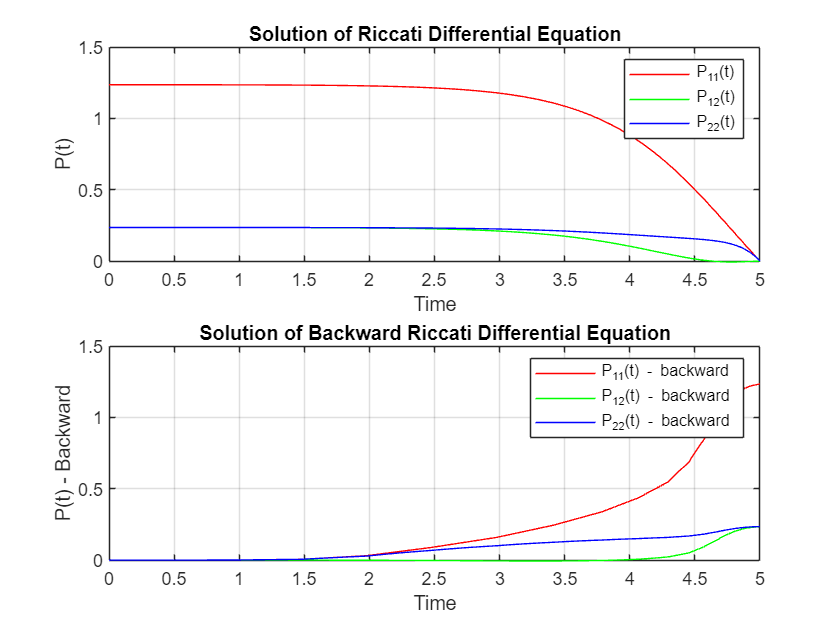

% Define system matrices
A = [0 1; -2 -3];
B = [0; 1];
Q = eye(2);
R = 1;
T = 5; % Terminal time

% Choose the terminal cost matrix S
% Option 1: Minimal terminal cost
S = zeros(2, 2);

% Option 2: Penalizing final state deviation
% S = 1 * eye(2);

% Option 3: Custom terminal cost for desired final state x_d
% x_d = [1; 0];
% S = 100 * (x_d * x_d');

% Solve the Riccati differential equation backward in time
tspan = [T 0];
P0 = S(:); % Terminal condition P(T) = S
[t, P] = ode45(@(t, P) riccati_ode(t, P, A, B, Q, R), tspan, P0);

% Reshape the solution to obtain P(t)
P = reshape(P', [2, 2, length(t)]);

% Plot the results
figure;
subplot(2, 1, 1);
plot(t, squeeze(P(1,1,:)), 'r', 'DisplayName', 'P_{11}(t)');
hold on;
plot(t, squeeze(P(1,2,:)), 'g', 'DisplayName', 'P_{12}(t)');
plot(t, squeeze(P(2,2,:)), 'b', 'DisplayName', 'P_{22}(t)');
xlabel('Time');
ylabel('P(t)');
legend;
title('Solution of Riccati Differential Equation');
grid on;

% Plot the backward solution
subplot(2, 1, 2);
plot(flip(t), squeeze(P(1,1,:)), 'r', 'DisplayName', 'P_{11}(t) - backward');
hold on;
plot(flip(t), squeeze(P(1,2,:)), 'g', 'DisplayName', 'P_{12}(t) - backward');
plot(flip(t), squeeze(P(2,2,:)), 'b', 'DisplayName', 'P_{22}(t) - backward');
xlabel('Time');
ylabel('P(t) - Backward');
legend;
title('Solution of Backward Riccati Differential Equation');
grid on;


% Compute the optimal control policy at initial time t=0
P0 = reshape(P(:, :, end), [2, 2]);
K = inv(R) * B' * P0;

fprintf('Optimal Feedback Gain K at t=0:\n');

Optimal Feedback Gain K at t=0:


disp(K);

    0.2360    0.2360



function dPdt = riccati_ode(t, P, A, B, Q, R)
    P = reshape(P, size(A)); % Convert from vector to matrix
    dPdt = -(A'*P + P*A - P*B*inv(R)*B'*P + Q); % Riccati equation
    dPdt = dPdt(:); % Convert from matrix to vector
end
